clc


**DH convention**

%Dimensions
L1 = 14.5;
L2 = 10.63;
L3 = 10.63;
L4 = 8.97;

%DH parameters
a = [0;L2;L3;L4];
alpha = [90;0;0;0] * pi/180;
d = [L1;0;0;0];
theta = [0;0;0;0];
sigma = zeros(4,1);
offset = [0;90;-90;0]* pi/180;

%Serial Link creation
DH_params = [theta d a alpha sigma offset];
Phantom = SerialLink(DH_params)

 
Phantom = 
 
noname (4 axis, RRRR, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       14.5|          0|      1.571|          0|
|  2|         q2|          0|      10.63|          0|      1.571|
|  3|         q3|          0|      10.63|          0|     -1.571|
|  4|         q4|          0|       8.97|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1          

Phantom.name = "PhantomX";
q = [0 0 0 0]*pi/180;
pose = Phantom.fkine(q)

pose =     1.0000         0         0   19.6000
         0    0.0000   -1.0000    0.0000
         0    1.0000    0.0000   25.1300
         0         0         0    1.0000


figure(1)
%Phantom.plot(q,'workspace',[-200 200 -200 200 0 500],'nobase','notiles')

**Inverse Kinematics from Forward Kinematics**

desiredPos = pose(1:3,4) 

desiredPos =    19.6000
    0.0000
   25.1300


desiredOrientation = pose(1:3,1:3)

desiredOrientation =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


approach = pose(1:3)'

approach =      1
     0
     0


theta1 = atan2(desiredPos(2),desiredPos(1));
rad2deg(theta1)

ans = 1.9027e-15

wristPos = desiredPos -  L4*approach

wristPos =    10.6300
    0.0000
   25.1300


**Inverse Kinematics from Custom**

desiredPos = [20.6;-4.6;13.0]

desiredPos =    20.6000
   -4.6000
   13.0000


desiredOrientation =[1 0 0;0 0 -1;0 1 0]

desiredOrientation =      1     0     0
     0     0    -1
     0     1     0


approach = desiredOrientation(1:3,1)

approach =      1
     0
     0


theta1 = atan2(desiredPos(2),desiredPos(1));
rad2deg(theta1)

ans = -12.5877

wristPos = desiredPos -  L4*approach

wristPos =    11.6300
   -4.6000
   13.0000


**Double-pendulum inverse kinematics**

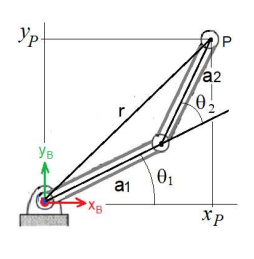

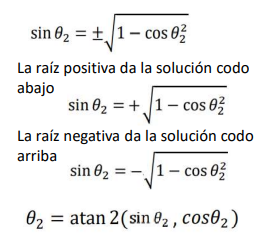

#### Caso codo arriba

#### Caso codo abajo

H01 = Phantom.A(1,theta1);
R10 = H01(1:3,1:3)';
t10 = -R10*H01(1:3,4);
H10 = [R10 t10;zeros(1,3) 1]

H10 =     0.9760   -0.2179         0         0
    0.0000    0.0000    1.0000  -14.5000
   -0.2179   -0.9760    0.0000   -0.0000
         0         0         0    1.0000


wristPos_1 =  H10*[wristPos;1] 

wristPos_1 =    12.3530
   -1.5000
    1.9549
    1.0000



cos_theta3 = (norm(wristPos_1(1:2))^2 - L2^2 - L3^2)/(2*L2*L3);
sin_theta3 = sqrt(1-cos_theta3^2);

theta3 = [atan2(sin_theta3,cos_theta3);atan2(-sin_theta3,cos_theta3)]

theta3 =     1.8911
   -1.8911


Se elige la configuarción codo abajo.

theta3 = theta3(2)

theta3 = -1.8911

rad2deg(theta3)

ans = -108.3502

k1 = L2+L3*cos(theta3);
k2 = L3*sin(theta3);
theta2 = atan2(wristPos_1(2),wristPos_1(1))-atan2(k2,k1)

theta2 = 0.8247

rad2deg(theta2)

ans = 47.2517

approach_1 = R10*approach

approach_1 =     0.9760
    0.0000
   -0.2179


phi = atan2(approach_1(2),approach_1(1))

phi = 1.3673e-17

theta4 = phi - theta2 - theta3;
rad2deg(theta4)

ans = 61.0986

theta = rad2deg([theta1 (theta2-pi/2) (theta3+pi/2) theta4])

theta =   -12.5877  -42.7483  -18.3502   61.0986


**Confirmation**

Q = Phantom.ikine(pose,deg2rad([theta]),[1 1 1 0 0 0])

Q =     0.0000   -0.3264   -0.1813    1.2004


rad2deg(Q)

ans =     0.0000  -18.6992  -10.3864   68.7755


function PlotRobot(Robot,q)
figure()
Robot.plot(q,'nobase','notiles')
zlim([0 5])
end